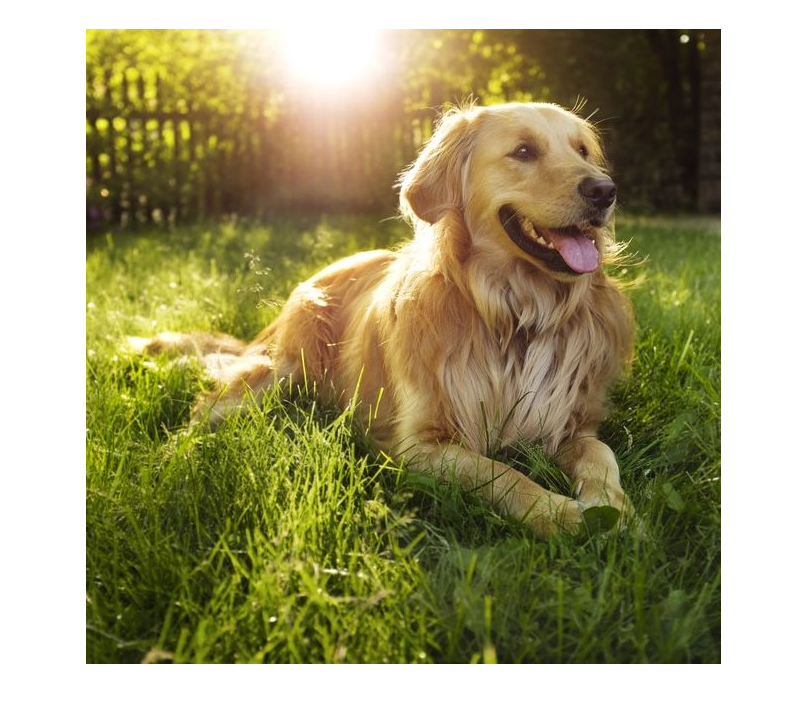


img = imread('squaredog.jpg');


imshow(img);

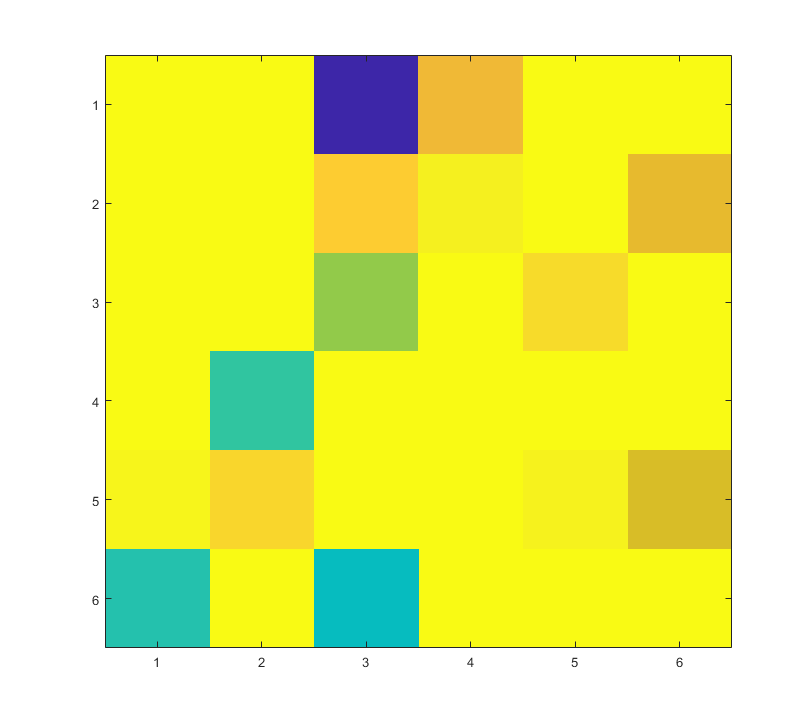

%PSF = fspecial('gaussian',randi([5,10]),randi([5,50])/10);
%PSF = fspecial('average',randi([5,10]));
%PSF = imnoise(zeros(randi([5,10])),"gaussian", 1);
imagesc(PSF);

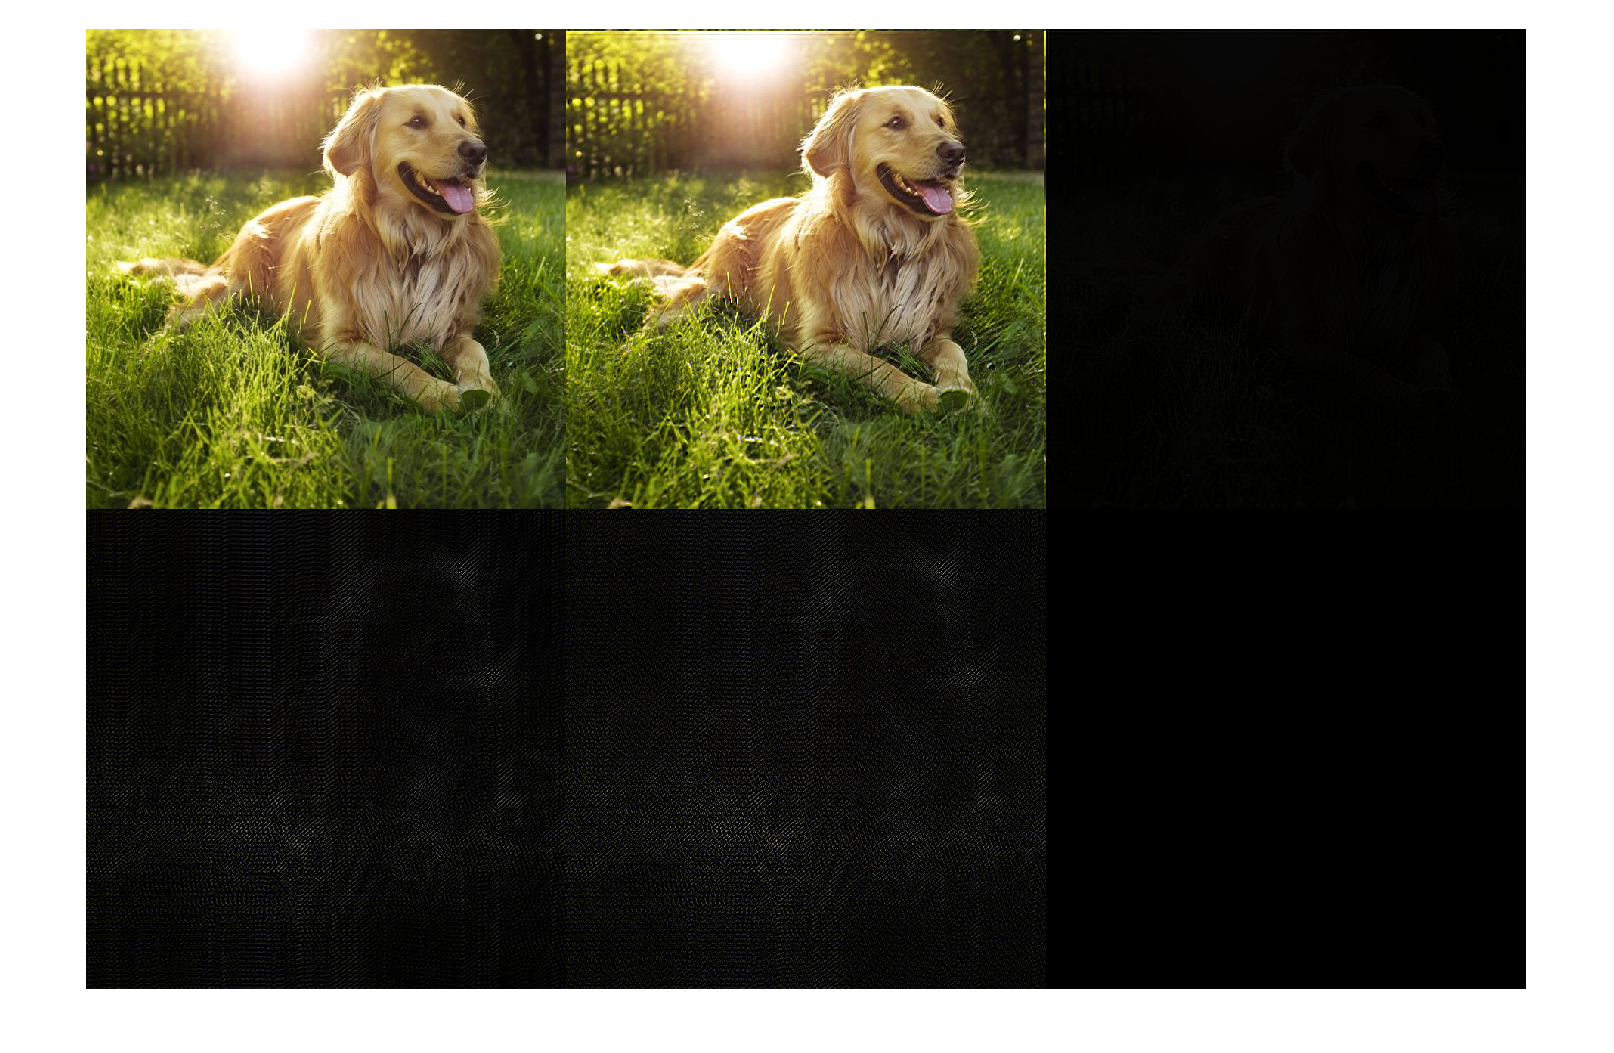

outImg1 = deconvblind(img,PSF);
outImg2 = deconvlucy(img,PSF);
outImg3 = deconvreg(img,PSF);
outImg4 = deconvwnr(img,PSF);


%imagesc(outImg);

montage({img,outImg1,outImg2,outImg3, outImg4});